# Accompanying MATLAB Code for *A Survey of Methods for the Discretization of Phonograph Record Playback Filters *

Presented at the 157th Convention of the Audio Engineeering Society (AES) in New York City, New York, 2024

Authors: Benjamin R Thompson and Tre DiPassio

Link to the Paper: INSERT

The sections labeled as "Interactive" are meant to walk the reader through the various methods for discritization that are defined in the paper

## 1) Introduction

As mentioned in Section 1 of the paper, almost all electrically recorded records are cut with some equalization that allows the cutter to switch between a constant-velocity response and a constant-amplitude response for different bands within the audible spectrum. For laterally-cut grooves, this allows for smaller groove widths and thus more information for a given area. If equalization is applied to a record when it is cut, an inverse equalization must be applied on playback to recover a flat frequency response. Since approximately 1954, the RIAA curve has been the standard equalization curve used to cut most records. The playback curve for records cut with the RIAA standard is depicted in by trace E below, modified from Moyer (Paper Reference [[10]](https://www.aes.org/aeshc/pdf/moyer_evolution-of-a-recording-curve.pdf)):

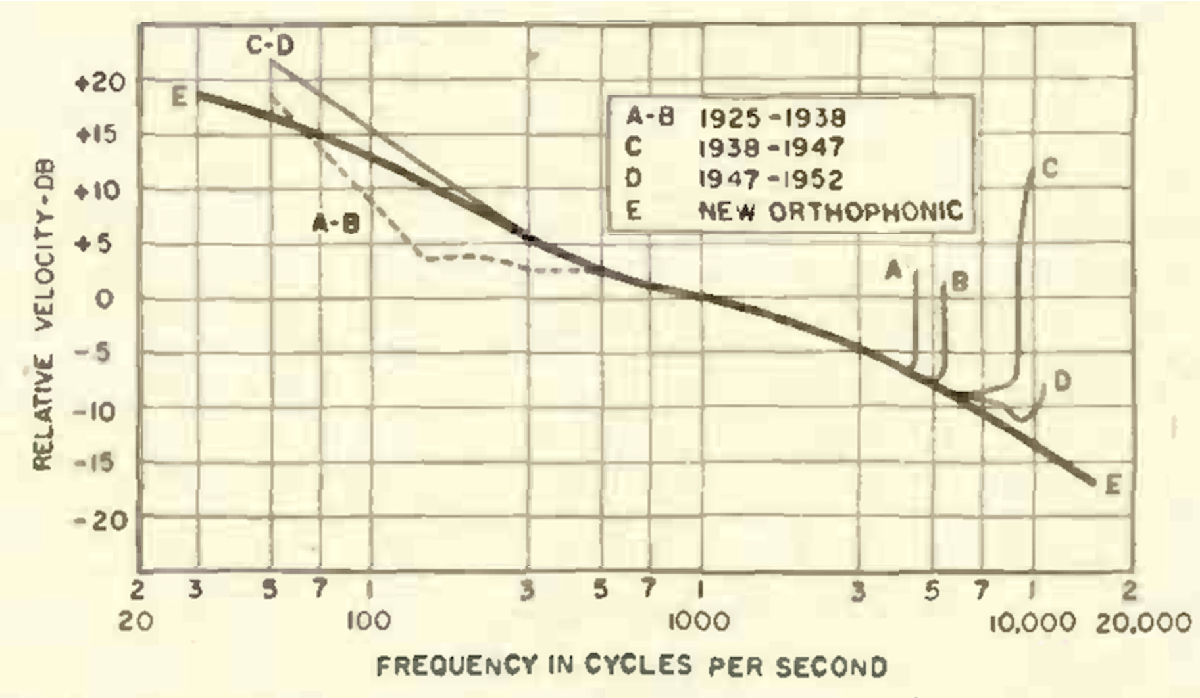

The RIAA standard curve is defined by three time constants that determine the curve's treble rolloff, bass boost, and bass shelving frequencies. Many playback curves are defined by three time constants, though older curves may require as few as a single time constant which would describe the turnover frequency for the bass boost. Most phonograph playback devices made after 1954 include analog circuity to apply the curve from the figure above. An example of a phono preamplifier with integrated RIAA playback equalization is depicted below. If you analyzed or simulated this circuit (Reproduced directly from *Small Signal Audio Design *by Douglas Self), you would get a transfer function that looked identical to the RIAA playback curve form trace E in the image above:

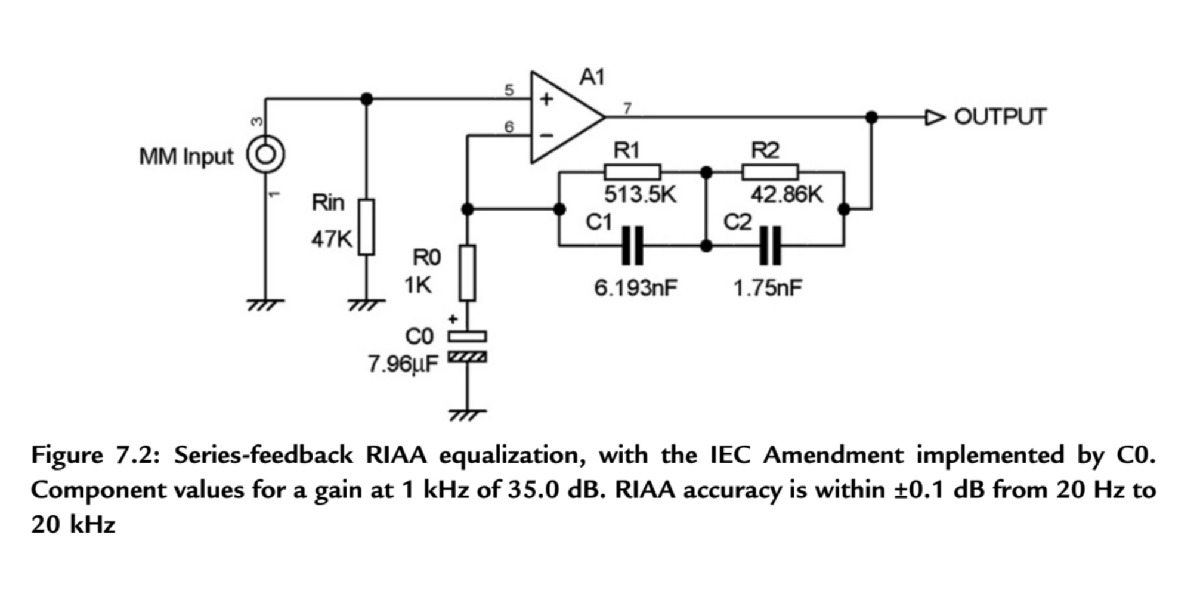

Before the adoption of the RIAA standard, the required playback curve for a disc could vary over time and from record company to record company. Therefore, anyone seeking to hear or restore the information from older discs must have access to multiple playback curves. This correction may be accomplished with either analog hardware or digital processing. The digital approach has the advantages of reduced cost and expanded versatility, but requires a transformation from continuous time, where the original curves are defined, to discrete time. This transformation inevitably comes with some deviations from the continuous-time response near the Nyquist frequency. There are many established methods for discretizing continuous-time filters, and these vary in performance, computational cost, and inherent latency. 

In the paper and in this MATLAB Live Script, we impliment several methods for performing this transformation in the context of phonograph record playback equalization. This script is intented to serve as a resource for anyone developing systems for digital playback equalization or similar applications that require approximating the response of a continuous-time filter digitally. The intention is by no means to declare a "winner", even for this specific application. Instead, it is meant to quantify some of the compromises of different approaches to discretization in a way that might be useful to those who find themselves developing systems for digital playback equalization or other applications where it is necessary to mimic an analog response in the digital domain.

## 2) Continuous Time RIAA System

In this MATLAB Live Script, we will use the RIAA playback equalization curve as a prototype filter to compare the various filter discretization methods. What is now known as the RIAA curve was developed by RCA Victor as the "New Orthophonic" curve and was published in 1953 (see paper reference [[10]](https://www.aes.org/aeshc/pdf/moyer_evolution-of-a-recording-curve.pdf)). This curve was adopted as a standard by a number of recording and broadcast organizations including the Recording Industry Association of America, eventually becoming a universal standard applied to all microgroove records (see paper reference [[7]](https://www.collinsaudio.com/Prosound_Workshop/Analogue%20Sound%20Restoration.pdf)). 

The original RIAA playback curve is defined by three time constants:

T0 = 318e-6;  % time constant for bass boost, in seconds
T1 = 75e-6;   % time constant for treble roll-off, in seconds
T2 = 3180e-6; % time constant for bass shelf, in seconds

The transfer function for this filter as defined by these time constants, with a gain factor applied such that the magnitude response at 1 kHz is approximately equal to 0 dB, can be written as follows (equation 2 from the paper):

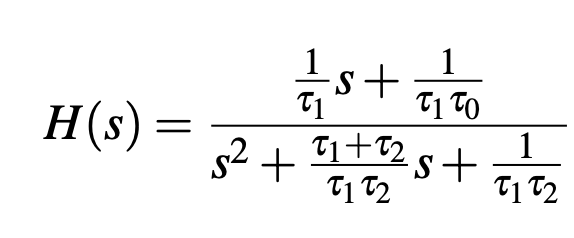	

We can represent the numerator and denominator of this transfer function in MATLAB as follows:

b0 = [0 1/T1 1/(T1*T0)];                % continuous time numerator 
a0 = [1 (T1+T2)/(T1*T2) 1/(T1*T2)];     % continuous time denominator 

We can then use MATLAB's tf function to make a continuous time transfer function object:

sdtf = tf(b0, a0) % make continuous transfer function object

sdtf =
 
     1.333e04 s + 4.193e07
  ---------------------------
  s^2 + 1.365e04 s + 4.193e06
 
Continuous-time transfer function.
Model Properties


As seen above, the s-domain transfer function (*sdtf*) varible is a continuous time transfer function which stores the numerator and denominator of the RIAA inverse filter using *s* as the complex variable. 

Let's first ensure that the response of this transfer function looks like the original inverse RIAA filter shown in Section 1 of this MATLAB Live Script. We can do this by performing an FFT with 'freqs' to generate a sampled frequency response.

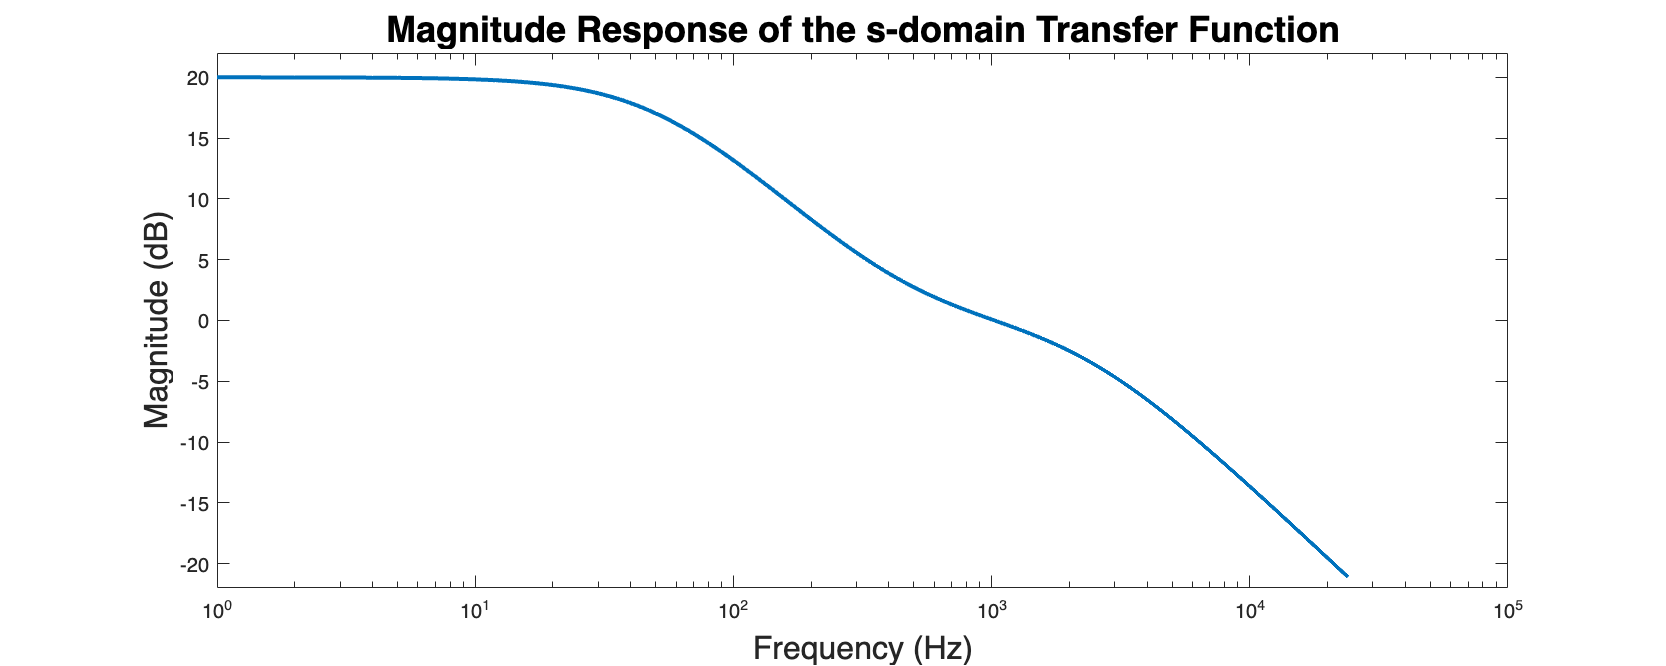

% Define the sampling rate (and sample period), which will be used throughout the Live Script:
fs = 48e3;  % Original sample rate of 48kHz
T = 1/fs;   % Original sample period

% Make a frequency array that has 1Hz resolution regardless of sample rate 
f = (0:fs/2-1)';
% Use the frequency array to make an array with units of radians/second:
radPerSec = (2*pi*f); 
% and divide the sampling rate to achieve an array with units of
% radians/sample:
radPerSample = radPerSec/fs;

% Use MATLABs 'freqs' function to make a complex freq response of s-domain
% transfer function using the numerator and denominator of the RIAA filter
H0 = freqs(b0,a0,radPerSec);

% Show that H0 looks like the inverse RIAA curve shown in Section 1 of this
% MATLAB Live Script:
figH0 = figure();
semilogx(radPerSec/(2*pi),mag2db(abs(H0)),'LineWidth',2); 
xlabel('Frequency (Hz)','FontSize',16);
ylabel('Magnitude (dB)','FontSize',16);
figH0.Position = [1 1 1000 400];
title('Magnitude Response of the s-domain Transfer Function','FontSize',18)
ylim([-22 22])

This response does match the inverse RIAA curve shown in Section 1 of this MATLAB Live Script! 

In addtion to analyzing the frequency repsonse of the analog filter and the discritized version, we will want to examine the time-domain reponses of each version. To that end we will now generate the impulse response of the s-domain filter, as well as a test impulse.

% length of the impulse response in seconds. The user can change this value
% if desired:
duration = 0.5;

% Create a time vector from 0 seconds to through the duration specified
% above in seconds:
t = 0:T:duration-T;

% Make a sampled IR from sdtf:
[h0, ~] = impulse(sdtf,t);
% Divide by the sample rate:
h0 = h0/fs;

% Make a test impulse
x = zeros(fs*duration,1); 
x(1) = 1;

You might notice that *h0* is here is a digital FIR filter that could be applied through **convolution** in the time domain to create a response that is identical to the s-domain tranfer funtion at the sampled frequency intervals (for that matter we could use *H0 *through multiplication in the frequency domain in much the same way). You might ask why we won't just use it directly instead of bothering with the other discretization methods presented here. The answer is that this FIR filter is not **order-preserving**, in that it requires convolution with an FIR filter with a length in samples of *duration * fs* to perform the equalization. 

FIRLength = length(h0)

FIRLength = 24000

Notice here that the numerator and denominator of the continuous time filter both have an original order of 2:

bOrderOriginal = length(b0)-1 % order of s-domain numerator 

bOrderOriginal = 2

aOrderOriginal = length(a0)-1 % order of s-domain denominator 

aOrderOriginal = 2

Instead, we want to create an **order-preserving**, infinite impulse response (IIR) filter. To match the s-domain transfer function, we want to produce a digitized, z-domain IIR filter with the same order as the continuous time system. The methods shown in this script will produce these second-order IIR filters, and allow an exploration of the advantages and trade-offs of each method.

## 3) Selecting Transform for Analysis - Interactive

Select a discretization method below to analyze when running the rest of the script. It is our recommendation to try each method, and compare their accuracies in repdocuding the inverse RIAA filter in both the magnitude and frequency domains

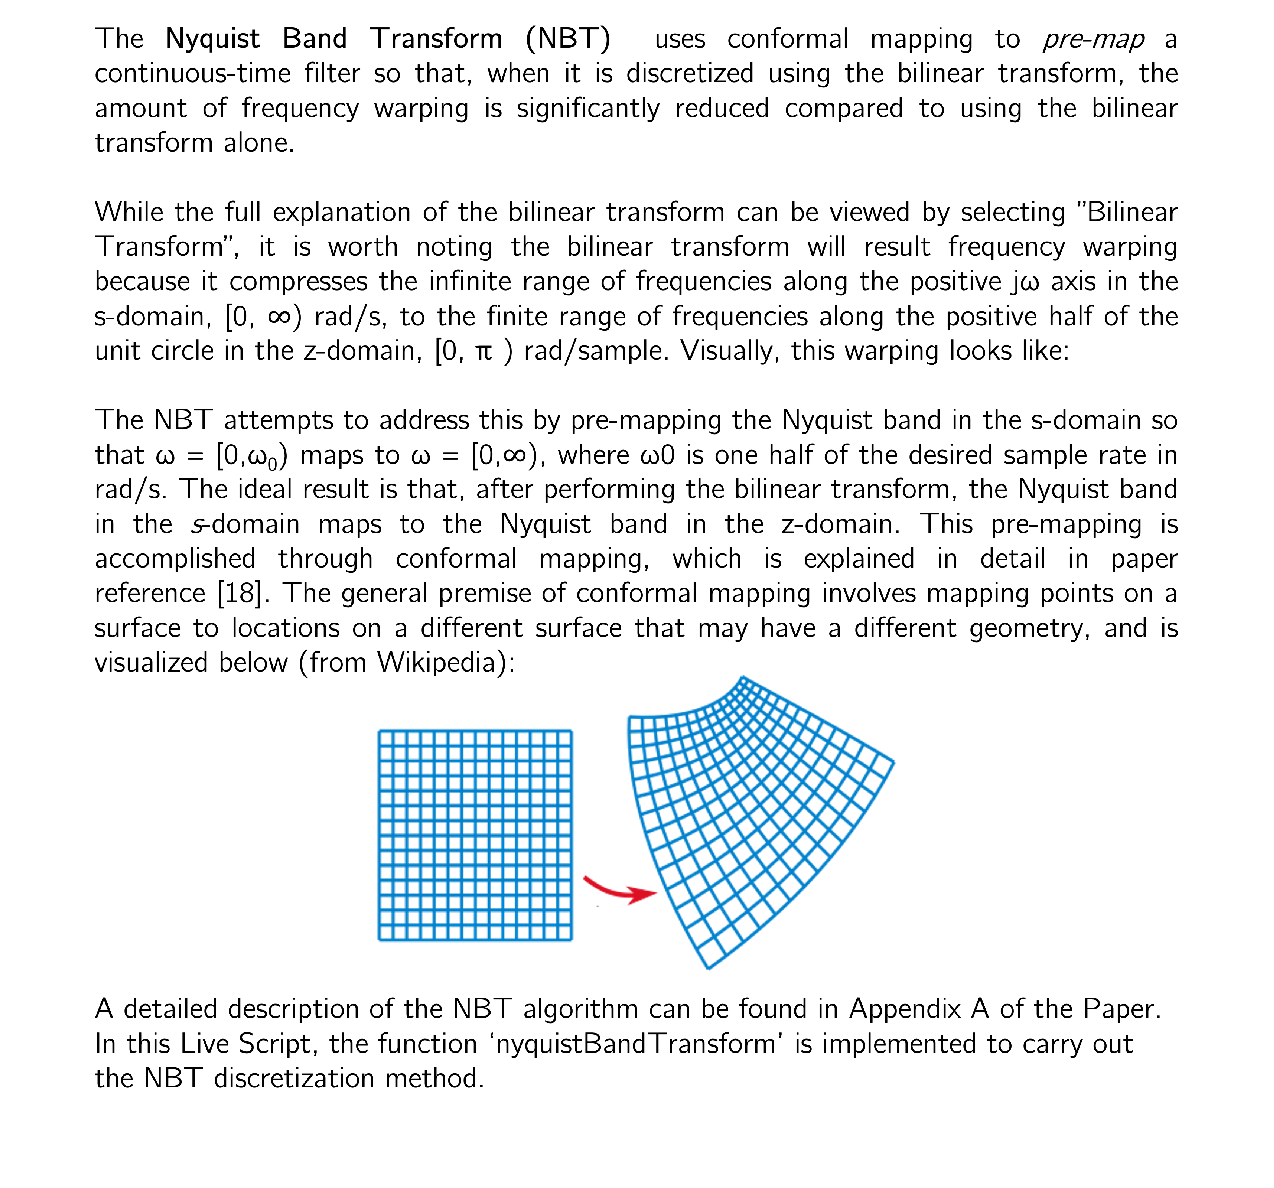

transformMethod = 7;
userFeedback(transformMethod);

## 4) Oversampling - Interactive

Most of the methods presented in this MATLAB Live Script can benefit from **oversampling**, the use of which results in a more accurate representation of the inverse RIAA filter. As stated in the paper, many of the inaccuracies that arise when using these discretization methods occur near the nyquist frequency (for a sampling frequency of 48,000 samples per second or Hz, the nyquist frequency is 24,000 Hz, which is near the audible band). When oversampling, you effectively raise the nyquist frequency of the signal. When you process the oversampled signal, you wind up with inaccuracies near the *new* nyquist frequency, though this frequency is now well outside the audible band, and will be filtered out when **downsampling** back to the original sampling rate. The impact of oversampling was demonstrated in the paper in Figure 2 for the Zero-Pole Matching discritization technique:

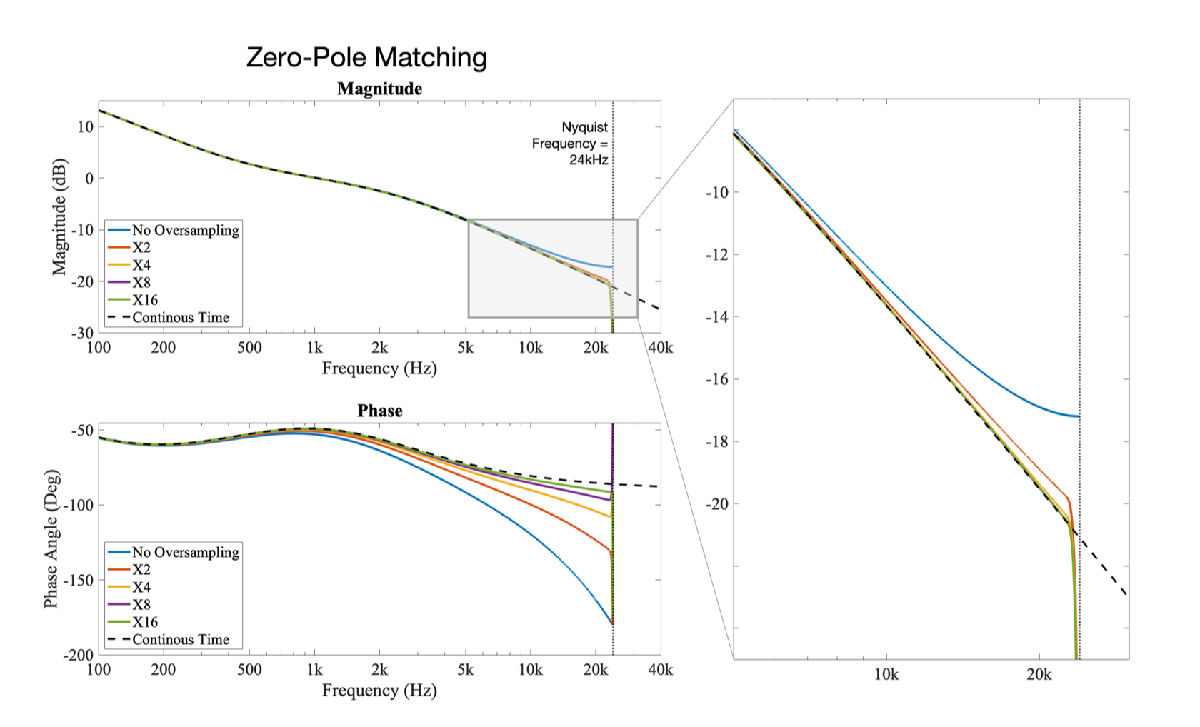

It is our reccomendation to try many values of oversampling for the provided discritization methods to see the effect that oversampling has on the accuracy of the discritzation method.

%%%%%%%%%%%%%%%% Setup Oversampling %%%%%%%%%%%%%%%%%%%
overSampleExp = 3;        % Oversampling exponent - upsample rate will be 2^overSampleExp*fs
fsUp = fs*2^overSampleExp;                   % Upsample rate based on the oversampling exponent
Tup = 1/fsUp;                                % Upsample period
[upFilts, downFilts] = getOverSamplingFilters(overSampleExp); % Get anti-alias/image filters, the verbose output is printed below:

designHalfbandFIR(TransitionWidth=0.05000000074505806, StopbandAttenuation=90, DesignMethod="equiripple", Passband="lowpass", Structure="interp", SystemObject=true)
designHalfbandFIR(TransitionWidth=0.05999999865889549, StopbandAttenuation=75, DesignMethod="equiripple", Passband="lowpass", Structure="decim", SystemObject=true)
designHalfbandFIR(TransitionWidth=0.10000000149011612, StopbandAttenuation=80, DesignMethod="equiripple", Passband="lowpass", Structure="interp", SystemObject=true)
designHalfbandFIR(TransitionWidth=0.11999999731779099, StopbandAttenuation=65, DesignMethod="equiripple", Passband="lowpass", Structure="decim", SystemObject=true)
designHalfbandFIR(TransitionWidth=0.10000000149011612, StopbandAttenuation=70, DesignMethod="equiripple", Passband="lowpass", Structure="interp", SystemObject=true)
designHalfbandFIR(TransitionWidth=0.11999999731779099, StopbandAttenuation=55, DesignMethod="equiripple", Passband="lowpass", Structure="decim", SystemObject=true)


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## 5) Processing - Interactive

Here, we impliment the discritization methods based on the option that is selected in Section 3 of this MATLAB Live Script:

%%%%%%%%%%%%%%%%%% Transforms %%%%%%%%%%%%%%%%%%%%
switch transformMethod
    case 0
        tic
        zdtf = c2d(sdtf,Tup,'zoh');
        procTime = toc;
        transformName = 'Zero-Order Hold';
        % discrete time coefficients 
        b1 = zdtf.Numerator{1}; 
        a1 = zdtf.Denominator{1};       
    case 1
        tic
        zdtf = c2d(sdtf,Tup,'foh');
        procTime = toc;
        transformName = 'Triangle Approximation';
        % discrete time coefficients 
        b1 = zdtf.Numerator{1}; 
        a1 = zdtf.Denominator{1};
    case 2
        Tup = 1/fsUp; % sample period at upsample rate
        tic
        zdtf = c2d(sdtf,Tup,'impulse');
        procTime = toc;
        transformName = 'Impulse Invariant';
        % discrete time coefficients 
        b1 = zdtf.Numerator{1}; 
        a1 = zdtf.Denominator{1};
    case 3
        tic
        zdtf = c2d(sdtf,Tup,'tustin');
        procTime = toc;
        transformName = 'Bilinear Transform';
        % discrete time coefficients 
        b1 = zdtf.Numerator{1}; 
        a1 = zdtf.Denominator{1};    
    case 4
        tic
        zdtf = c2d(sdtf,Tup,'matched');
        procTime = toc;
        transformName = 'Zero-Pole Matching';
        % discrete time coefficients 
        b1 = zdtf.Numerator{1}; 
        a1 = zdtf.Denominator{1};    
    case 5
        fUp = (0:fsUp/2-1)'; % 1Hz resolution regardless of sample rate 
        radPerSecUp = (2*pi*fUp); % rad/sample array
        radPerSampleUp = radPerSecUp/fsUp; % rad/sample array
        H0Up = freqs(b0,a0,radPerSecUp); % complex freq response of s-domain transfer function
        wts = getBkWts((0:fsUp/2-1)');
        tic
        [b1,a1] = invfreqz(H0Up,radPerSampleUp,bOrderOriginal,aOrderOriginal,wts,1e2,0.001);
        procTime = toc;
        transformName = 'Complex Error Minimization';
    case 6
        Nfft = fs;
        tic
        [b1,a1] = invFreqzMagOnly(b0,a0,fsUp,Nfft,bOrderOriginal,aOrderOriginal);
        procTime = toc;
        transformName = 'Magnitude Error Minimization';
    case 7
        Nfft = fs;
        [b1,a1,procTime] = nyquistBandTransform(b0,a0,fsUp,aOrderOriginal);
        transformName = 'Nyquist Band Transform';

end 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### 5.1) Upsampling 

for stage = 1:overSampleExp
    x = upFilts{stage}(x); 
end

y = filter(b1,a1,x); % filter 
yIR = x; % maintain an unfiltered, but oversampled impulse for calculating delay

% downsample
for stage = overSampleExp:-1:1
    y = downFilts{stage}(y); 
    yIR = downFilts{stage}(yIR); 
end

### 5.2) Label

delay = grpdelay(yIR); % group delay at all freq bins
delay = delay(1); % just group delay of first bin - TODO: why do you lose linear phase at higher overSampleExps
delayInt = round(delay); % for offsetting impulse in plot

[H1, ~] = freqz(y,1,fs/2,fs);  % complex freq response of discrete system

h0 = [zeros(delayInt,1); h0(1:end-delayInt,1)]; % offset continues time IR to delay of discrete system

% create phase compensation array to undo linear phase shift in plot
phaseComp = ((f/fs)*2*pi)*delay; 

H1ang = unwrap(angle(H1))+phaseComp; % add phase compensation

testFreq = 20e3;
testIdx = find(f>=testFreq,1);
magError = abs(mag2db(abs(H0(testIdx))/abs(H1(testIdx))));
phaseError = abs(rad2deg(angle(H0(testIdx))-H1ang(testIdx)));

normFact = max(abs(h0)); % normalization factor for time domain 

% normalize time domain signals 
h0 = h0/normFact;
y = y/normFact;

### 5.3) Calculating Mean Squared Error (MSE)

% find frequency index closest to 20 Hz 
twentyHzIdx = find(f >= 20,1); % this should always be equal to 21
% find frequency index closest to 20 kHz
twentyKhzIdx = find(f >= 20e3,1); % this should always be equal to 20001
H0BandLim = H0(twentyHzIdx:twentyKhzIdx); % H0 bandlimited 0-20kHz
H1BandLim = H1(twentyHzIdx:twentyKhzIdx); % H1 bandlimited 0-20kHz
fBandLim = f(twentyHzIdx:twentyKhzIdx);

% find time index closest to 0.01 seconds
timeIdx = find(t == 0.01,1); 
posIdxs = [abs(0.01-t(timeIdx)),abs(0.01-t(timeIdx-1))];
[~, IdxTemp] = min(posIdxs);
timeIdx = timeIdx-(IdxTemp-1);

% TODO: check this math
rmseTime = mean(abs(h0(1:timeIdx)-y(1:timeIdx))); % TODO: Should this be calculated over less time? Rn it dpeends on duration. 

magErrorAll = abs(mag2db(abs(H0BandLim)./abs(H1BandLim)));
weights = getBkWts(fBandLim);
magErrorWeighted = weights.*magErrorAll;
magErrorAve = sum(magErrorWeighted)/sum(weights);

phaseErrorAbs = abs(rad2deg(angle(H0BandLim))-rad2deg(H1ang(twentyHzIdx:twentyKhzIdx)));
phaseErrorSqWeighted = weights.*phaseErrorAbs;
rmsePhase = sum(phaseErrorSqWeighted)/sum(weights);


### 5.4) Plotting

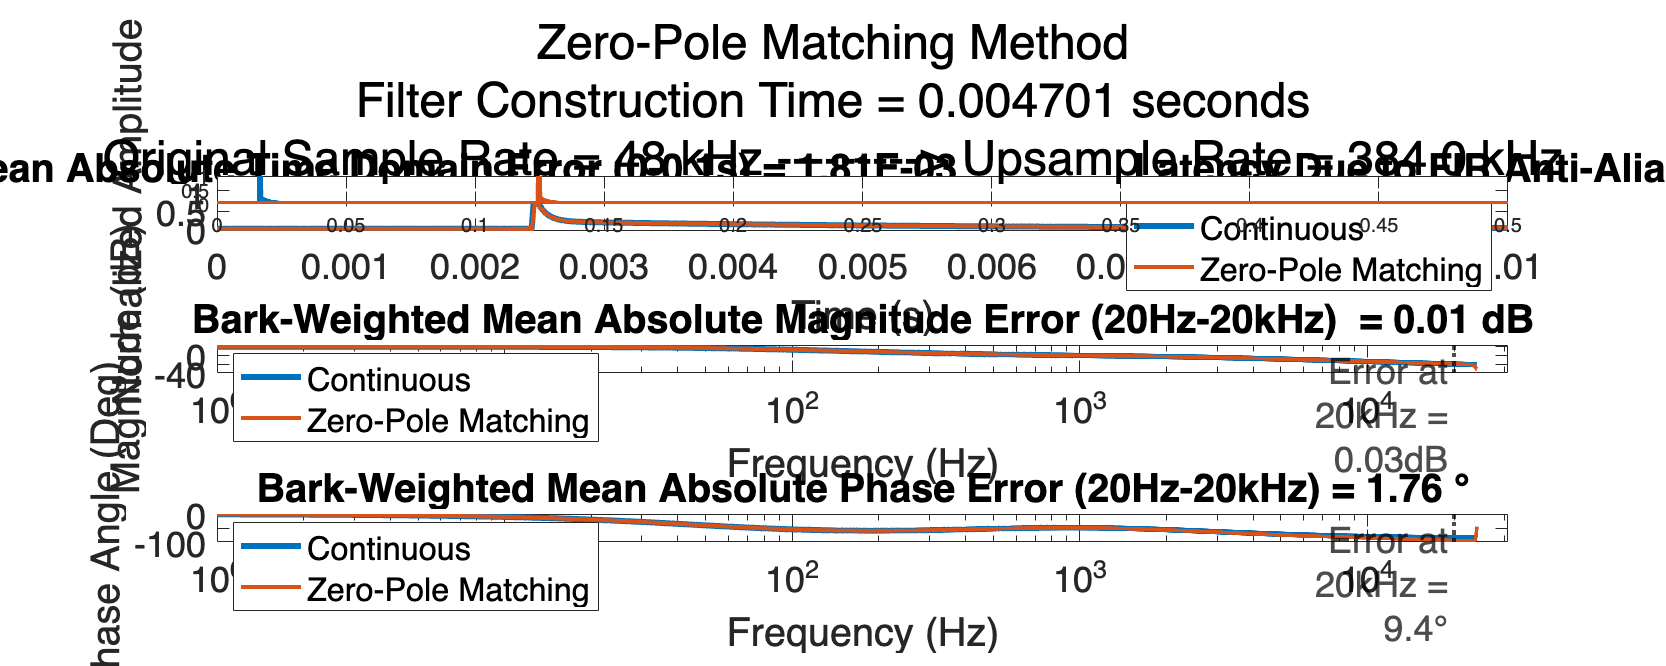

legendStr = ["Continuous", transformName];

if fsUp >= 1e6
    upFsStr = [num2str(fsUp/1e6,'%.2f') ' MHz'];
else
    upFsStr = [num2str(fsUp/1e3,'%.1f') ' kHz'];
end

fig = figure(2);

spaceStr = ' ---------> ';
sgtitle(horzcat(transformName, ' Method', newline, ...
    'Filter Construction Time = ', num2str(procTime), ' seconds',  newline, ...
    'Original Sample Rate = ', num2str(fs/1000, '%.0f'), ' kHz', spaceStr, ...
    'Upsample Rate = ', upFsStr), ...
    fontsize = 24)
subplot(3,1,1)
plot(t,h0,LineWidth=3)
hold on 

plot(t,y,LineWidth=2)

Error using plot
Vectors must be the same length.

hold off
legend(legendStr, Location='northeast')
title(horzcat('Normalized Mean Absolute Time Domain Error (0-0.1s) = ', num2str(rmseTime,'%.2E'), ...
'                ' ...
, 'Latency Due to FIR Anti-Alias Filters = ', num2str((delay*T)*1000,'%.2f'), 'ms'))
xlabel("Time (s)")
ylabel("Normalized Amplitude")
xlim([0 0.01])
set(gca,fontsize=18);

subplot(3,1,2)
semilogx(f,mag2db(abs(H0)),LineWidth=3)
hold on
semilogx(f,mag2db(abs(H1)),LineWidth=2)
xline(testFreq,LineWidth=2,Label=['Error at' newline '20kHz =' newline num2str(magError,'%.2f') ...
    'dB'],Color='k',LineStyle=':',FontSize=18,LabelOrientation='horizontal',...
    LabelHorizontalAlignment='left',LabelVerticalAlignment='top')
hold off
legend(legendStr, Location='southwest')
title(['Bark-Weighted Mean Absolute Magnitude Error (20Hz-20kHz)  = ' num2str(magErrorAve,'%.2f') ' dB'])
xlabel("Frequency (Hz)")
ylabel("Magnitude (dB)")
xlim([0 fs/2+0.1*fs+2000])
ylim([-40 24])
set(gca,fontsize=18);

subplot(3,1,3)
semilogx(f,rad2deg(angle(H0)),LineWidth=3)
hold on
semilogx(f,rad2deg(H1ang),LineWidth=2)

xline(testFreq,LineWidth=2,Label=['Error at' newline '20kHz =' newline num2str(phaseError,'%.1f') char(176) newline newline newline], ...
    Color='k',LineStyle=':',FontSize=18,LabelOrientation='horizontal',...
    LabelHorizontalAlignment='left',LabelVerticalAlignment='top')
hold off
legend(legendStr, Location='southwest')
title(['Bark-Weighted Mean Absolute Phase Error (20Hz-20kHz) = ' num2str(rmsePhase,'%.2f') ' ' char(176)])
xlim([0 fs/2+0.1*fs+2000])
xlabel("Frequency (Hz)")
ylabel("Phase Angle (Deg)")
set(gca,fontsize=18);

## 6) Comparing Results

In this section, we show some selected results

## 7) Helper Functions

In this section, we define helper functions for many of the discritization methods shown above:

### 7.1) getOverSamplingFilters

function [upFilts, downFilts] = getOverSamplingFilters(numStages)

    upFilts = cell(numStages,1);
    downFilts = cell(numStages,1);

    for stage = 1:numStages    
        if stage == 1
            twUp = single(0.05);
            twDown = single(0.06);
        else
            twUp = single(0.10);
            twDown = single(0.12);
        end
        
        gaindBStartUp    = -90.0;
        gaindBStartDown  = -75.0;
        gaindBFactorUp   =  10.0;
        gaindBFactorDown =  10.0;
        
        SBAup=gaindBStartUp + gaindBFactorUp * (stage-1);
        SBAdown=gaindBStartDown + gaindBFactorDown * (stage-1);

        upFilts{stage} = getUpFilts(SBAup,twUp);
        downFilts{stage} = getDownFilts(SBAdown, twDown);

    end
end

### 7.2) getUpFilts

function [c] = getUpFilts(amplitudedB, normalisedTransitionWidth)
    c = designHalfbandFIR(TransitionWidth=normalisedTransitionWidth, ...
                            StopbandAttenuation=-1*amplitudedB, SystemObject=true, ...
                            Structure='interp', DesignMethod="equiripple", Verbose=true);
end



### 7.3) getDownFilts

%%
function [c] = getDownFilts(amplitudedB, normalisedTransitionWidth)
    c = designHalfbandFIR(TransitionWidth=normalisedTransitionWidth, ...
                            StopbandAttenuation=-1*amplitudedB, SystemObject=true, ...
                            Structure='decim', DesignMethod="equiripple", Verbose=true);
end


### 7.4) invFreqzMagOnly

function [b, a] = invFreqzMagOnly(bs, as, fs, Nfft, NZ, NP)

% bs: s-domain numerator 
% as: s-domain denominator 
% fs: sample rate for discritization 
% Nfft: fft length (number of frequencies at which to sample
    % analog freq response including negative frequencies)
% Nz: desired number of zeros
% Np: desired number of poles

% Adapted from "Physical Audio Signal Processing" by Julius Orion Smith III, November 8, 2010
% https://www.dsprelated.com/freebooks/pasp/Fitting_Filters_Measured_Amplitude.html

    fk = fs*[0:Nfft/2]/Nfft; % fft frequency grid (nonneg freqs)
    radPerSec = 2*pi*fk;
    H0 = freqs(bs,as,radPerSec); % analog frequency response sampled at fk  
    Gfk = abs(H0);
    Ns = length(Gfk);

    S = [Gfk,Gfk(Ns-1:-1:2)]; % install negative-frequencies
    Sdb = mag2db(S);

    c = ifft(Sdb); % compute real cepstrum from log magnitude spectrum
    % Fold cepstrum to reflect non-min-phase zeros inside unit circle:
    cf = [c(1), c(2:Ns-1)+c(Nfft:-1:Ns+1), c(Ns), zeros(1,Nfft-Ns)];
    Cf = fft(cf); % = dB_magnitude + j * minimum_phase
    Smp = 10 .^ (Cf/20); % minimum-phase spectrum
    
    Smpp = Smp(1:Ns); % nonnegative-frequency portion
    % wt = 1 ./ (fk+1); % typical weight fn for audio
    wk = 2*pi*fk/fs;
    wt = getBkWts(fk);
    [b,a] = invfreqz(Smpp,wk,NZ,NP,wt,1e3,1e-6);

end


### 7.5) nyquistBandTransform


function [b, a, compTime] = nyquistBandTransform(bs, as, fs, order)

% bs: s-domain numerator 
% as: s-domain denominator 
% fs: sample rate for discritization 
% order: order of bs, as - these should be the same, zero pad if necessary

% b: z-domain numerator
% a: z-domain denominator
% compTime: computation time excluding matrix construction which could be
% pre-computed in many use cases

    N = order;
    Omega0 = pi*fs; % nyquist frequency in rad/sec
    T = 1/fs; % sample period 

    % EQ. 39 in Nyquist Band Transform: An Order-Preserving Transform for
    % Bandlimited Discretization with modification: "The formulation in Eq.
    % (39) can also be used to apply the first transform Eq. (26) by swapping
    % Omega0^2 for -Omega0^2 and replacing Upsilon with −2*Omega0*OmegaC". OmegaC is
    % set equal to Omega0
    A0 = zeros(2*N+1,N+1);
    for n = 0:N
        for k = 0:n
            A0(N-n+2*k+1,(n+1)) = (-2*Omega0^2)^(N-n)*nchoosek(n,k)*(-1*Omega0^2)^(n-k);
        end
    end
    
    A0 = flip(A0,1);

    % Uplison is a free paramater that allows perfedct matching for one
    % frequency via EQ. 64 in Nyquist Band Transform: An Order-Preserving Transform for
    % Bandlimited Discretization
    % Uplsilon = 2*(((2/T)*tan((Omega_a*T)/2))/Omega_a)*sqrt(1-((Omega_a*T)/pi)^2);
    
    % "If there is no a priori of the system, a possible choice for γ is to set
    % Omega_a = (π*fs)/2: half the Nyquist limit. This results in a γ =
    % 4*(3^0.5)*π*fs^2 ≈ 2.2*Omega0^2"    
    % Upsilon = 2.2*Omega0^2;

    % Alternately, Upsilon can be optimized to give the smallest amount of
    % frequency warping accross some bandwidth with some weighting. The
    % following values are optimized to give the least mean absolute error
    % in frequency mapping from 20Hz-20kHz for each sample rate:

    % MAE 20Hz-20kHz
    switch fs
        case 48e3
            UpsilonHat = 2.0029;
        case 96e3 
            UpsilonHat = 2.0009;
        case 192e3 
            UpsilonHat = 2.0003;
        case 384e3 
            UpsilonHat = 2.0001;
        case 768e3 
            UpsilonHat = 2;
        otherwise
            UpsilonHat = 2;
            
    end
    
    % MSE 20Hz-20kHz
    % switch fs
    %     case 48e3
    %         UpsilonHat = 2.0781;
    %     case 96e3 
    %         UpsilonHat = 2.0284;
    %     case 192e3 
    %         UpsilonHat = 2.0078;
    %     case 384e3 
    %         UpsilonHat = 2.0020;
    %     case 768e3 
    %         UpsilonHat = 2.0005;
    %     case 1.536e6
    %         UpsilonHat = 2.0001;
    %     otherwise
    %         UpsilonHat = 2;
    % end

    Upsilon = UpsilonHat*Omega0^2;

    % EQ. 39 in Nyquist Band Transform: An Order-Preserving Transform for
    % Bandlimited Discretization.
    % OmegaC is set equal to Omega0
    A = zeros(2*N+1,N+1);
    for n = 0:N
        for k = 0:n
            A(N-n+2*k+1,(n+1)) = (Upsilon)^(N-n)*nchoosek(n,k)*(Omega0^2)^(n-k);
        end
    end
    
    A = flip(A,1);
    
    Aplus = pinv(A);

    tic;
    
    % first forward transform
    kb = A0*bs.'; 
    ka = A0*as.';

    % Stabilize the mapped coefficients κa and enforce minimum/maximum phase
    % on κb
    
    [z,p,k] = tf2zp(kb.',ka.');
    pImag = imag(p);
    pReal = real(p);
    pRealStable = abs(pReal)*-1;
    pStable = pRealStable+pImag;
    
    zImag = imag(z);
    zReal = real(z);
    zRealStable = abs(zReal)*-1;
    zMinPhase = zRealStable+zImag;
    
    [kbStable, kaStable] = zp2tf(zMinPhase,pStable,k);

    % second inverse transform
    cb = Aplus*kbStable.';
    ca = Aplus*kaStable.';

    % bilinear transform
    sdtf = tf(cb.', ca.');
    opts = c2dOptions;
    opts.Method = 'tustin';
    zdtf = c2d(sdtf,T,opts);

    % discrete time coefficients 
    b = zdtf.Numerator{1}; 
    a = zdtf.Denominator{1};  

    compTime = toc;
end

### 7.6) getBkWts

function bkWts = getBkWts(freq)
    % Returns an array of weights the same length as freq where each weight
    % equals 1 divided by the bandwidth of the Bark band that the corresponding
    % frequency falls in

    % freq: An array of frequencies in Hz

    barkBandEdges = [0, 100, 200, 300, 400, 510, ...
        630, 770, 920, 1080, 1270, 1480, 1720, ...
        2000, 2320, 2700, 3150, 3700, 4400, 5300, ...
        6400, 7700, 9500, 12000, 15500, 20500, 27001];

    if freq < 0
        error("min frequency = 0 Hz")
    end

    if freq > barkBandEdges(27)
        error("max frequency = 26,999 Hz")
    end

    % make array of bandwidths corresponding to each Bark band
    barkBandWidths = zeros(length(barkBandEdges)-1,1);
    for idx = 1:length(barkBandWidths)
        barkBandWidths(idx) = barkBandEdges(idx+1)-barkBandEdges(idx);
    end

    bkWts = zeros(length(freq),1);

    % for each frequency, find the Bark band that it falls into and fill the
    % corresponding index in bkWts with 1 divided by the bandwidth of that
    % band
    for idx = 1:length(bkWts)
        if freq(idx) < barkBandEdges(2)
            bkWts(idx) = 1/barkBandWidths(1);    
        elseif freq(idx) < barkBandEdges(3)
            bkWts(idx) = 1/barkBandWidths(2);
        elseif freq(idx) < barkBandEdges(4)
            bkWts(idx) = 1/barkBandWidths(3);        
        elseif freq(idx) < barkBandEdges(5)
            bkWts(idx) = 1/barkBandWidths(4);
        elseif freq(idx) < barkBandEdges(6)
            bkWts(idx) = 1/barkBandWidths(5);        
        elseif freq(idx) < barkBandEdges(7)
            bkWts(idx) = 1/barkBandWidths(6);
        elseif freq(idx) < barkBandEdges(8)
            bkWts(idx) = 1/barkBandWidths(7);
        elseif freq(idx) < barkBandEdges(9)
            bkWts(idx) = 1/barkBandWidths(8);
        elseif freq(idx) < barkBandEdges(10)
            bkWts(idx) = 1/barkBandWidths(9);
        elseif freq(idx) < barkBandEdges(11)
            bkWts(idx) = 1/barkBandWidths(10);
        elseif freq(idx) < barkBandEdges(12)
            bkWts(idx) = 1/barkBandWidths(11);
        elseif freq(idx) < barkBandEdges(13)
            bkWts(idx) = 1/barkBandWidths(12);
        elseif freq(idx) < barkBandEdges(14)
            bkWts(idx) = 1/barkBandWidths(13);
        elseif freq(idx) < barkBandEdges(15)
            bkWts(idx) = 1/barkBandWidths(14);
        elseif freq(idx) < barkBandEdges(16)
            bkWts(idx) = 1/barkBandWidths(15);
        elseif freq(idx) < barkBandEdges(17)
            bkWts(idx) = 1/barkBandWidths(16);
        elseif freq(idx) < barkBandEdges(18)
            bkWts(idx) = 1/barkBandWidths(17);
        elseif freq(idx) < barkBandEdges(19)
            bkWts(idx) = 1/barkBandWidths(18);
        elseif freq(idx) < barkBandEdges(20)
            bkWts(idx) = 1/barkBandWidths(19);
        elseif freq(idx) < barkBandEdges(21)
            bkWts(idx) = 1/barkBandWidths(20);
        elseif freq(idx) < barkBandEdges(22)
            bkWts(idx) = 1/barkBandWidths(21);
        elseif freq(idx) < barkBandEdges(23)
            bkWts(idx) = 1/barkBandWidths(22);
        elseif freq(idx) < barkBandEdges(24)
            bkWts(idx) = 1/barkBandWidths(23);
        elseif freq(idx) < barkBandEdges(25)
            bkWts(idx) = 1/barkBandWidths(24);
        elseif freq(idx) < barkBandEdges(26)
            bkWts(idx) = 1/barkBandWidths(25);
        elseif freq(idx) < barkBandEdges(27)
            bkWts(idx) = 1/barkBandWidths(26);
        end
    end
end




### 7.7) userFeedback


function [] = userFeedback(transformMethod)
    % 0: Zero-Order Hold
    % 1: Triangle Approximation
    % 2: Impulse Invariant 
    % 3: Bilinear
    % 4: Zero-Pole Matching
    % 5: Curve Fitting (Complex)
    % 6: Curve Fitting (Magnitude Only) 
    % 7: Nyquist Band Transform

    addpath('assets/');

    switch transformMethod
        case 0
            %Zoh
            imshow('Method0.png');
        case 1
            %Triangle
            imshow('Method1.png');
        case 2
            % Impulse
            imshow('Method2.png');
        case 3
            % Bilinear
            imshow('Method3.png');
        case 4
            %ZPMatching  
            imshow('Method4.png');
        case 5
            % Complex Curve Fitting
            imshow('Method5.png');
        case 6
            % Curve Fitting Magnitude
            imshow('Method6.png');
        case 7
            % Nyquist band transform
            imshow('Method7.png');
    
    end 



end